lid = LIDAR('COM11')

Error using serial/fopen (line 72)
Open failed: Port: COM11 is not available. Available ports: COM3, COM6, COM8.
Use INSTRFIND to determine if other instrument objects are connected to the requested device.

Error in LIDAR (line 26)
            fopen(obj.lidar);                   %connects the serial port object, the lidar

lid.scan(400);

fprintf(lid.lidar, 'QT');
fclose(lid.lidar);
clear lidar;
warning('on');
disp("the lidar has successfully been terminated")

clear
clc
%camList = webcamlist()
cam = Camera();

camera.show()

n = 5
data = zeros(n, 4)
for i = 1:n
    data(i, 4) = input("actual distance")
    newPosition = -1;
    while newPosition == -1
    [newPosition, pose, tag] = camera.updatePositionApril()
    end
    distance = sqrt(newPosition(1)^2 + newPosition(3)^2);
    angle = 90
    xOffSet = distance * cosd(angle);
    yOffSet = distance * sind(angle);
    Position = [xOffSet, yOffSet];
    matrix = transpose(pose(1,1).T)
    %v = [0, 0, 0, 1] * (pose(1,1).T)^-1;
    v =  transpose(pose(1,1).T) * [0; 0; 0; 1];
    
    data(i, 1) = v(3)
    data(i, 2:3) = Position
end

data1 = data


%data(:, 4) = [18; 24; 30; 36; 42]
data(:, 4) = data(:,4)*2.54/100

data =     0.9238         0    0.9239    0.3048
    2.1375         0    2.1375    0.7620
    3.2559         0    3.2559    1.2192
    4.4803         0    4.4808    1.6764
         0         0         0         0


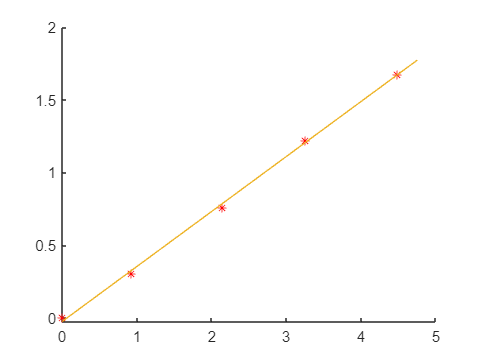

clf
hold on
plot(data(:,1), data(:,4), 'b*')
plot(data(:,3), data(:,4), 'r*')
[m,b] = polyfit(data(:,1), data(:,4), 1);
x = [0;4.75];
y = x*m(1) + m(2);
plot(x,y)


[id,loc,pose] = cam.poses()

cam.disp_tags();

imshow(ans)

while true
    
    imshow(cam.disp_tags())
    pause(1)
end

[id, loc, poses] = cam.poses()

neo = NEO_M8U_USB("COM13") 

basic_data = neo.getBasic() 

  [robotArduino]= SETUPARDUINO('COM6')   

        % semi-colon left off to confirm Nano is connected

clear drive;
drive = servo(robotArduino, 'D3', 'MinPulseDuration', 1500*10^-6, 'MaxPulseDuration', 1550*10^-6);
writePosition(drive, 0.5);      % always start servo-command at 0.5

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end